# `The freqtag pipeline: A principled approach to analyzing electrophysiological time series in frequency tagging paradigms. Part 1: Measuring the time-varying ssVEP envelope at each tagging frequency. `

## 1-Load the 3-D file (129 electrodes x 3901 time points x 39 trials)

    - Download exampledata_1.mat from [https://osf.io/e5vuf/](https://osf.io/e5vuf/) and copy into freqtag folder. 

    - Each trial contains  400ms pre- and 7400ms post-stimulus onset;

    - During each trial, two spatially overlapping stimuli flicker at different frequencies (5 Hz and 6 Hz), 

clear
close('all')
load('exampledata_1.mat') 
exampledata_1 = data_1; % Renaming the data to keep it a bit simpler

## 2-Plot the data, averaging the trials

    -The first visualization serves as a sanity check by plotting the data as a time domain average (i.e. ERP).

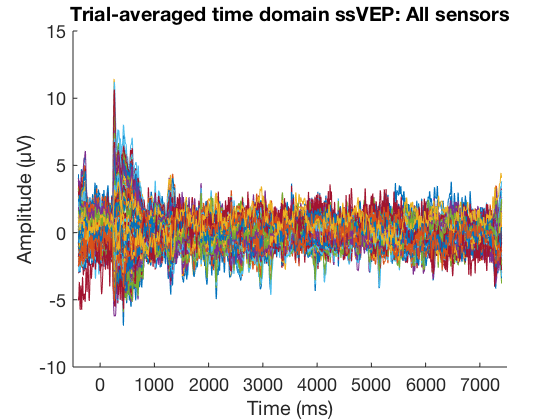

taxis = -400:2:7400; % this is the time axis for the segmented data
figure(1), plot(taxis, mean(exampledata_1,3)') %%Average the third dimension (trial dimension), plot all asensors
axis([-500 7500 -10 15])

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Time (ms)'), ylabel('Amplitude (μV)'); %label the axis 
title([ 'Trial-averaged time domain ssVEP: All sensors' ])

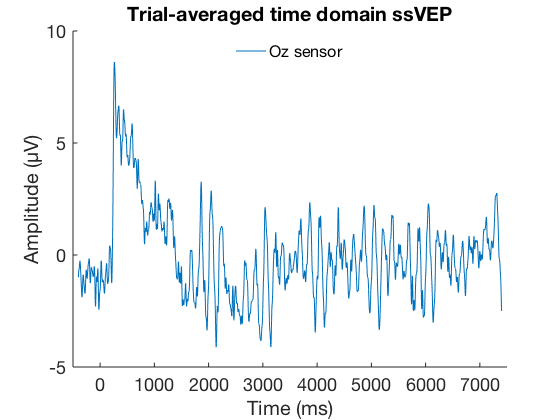


ERP = mean(exampledata_1, 3); % calculate the time domain average across trials (3rd dimension)

figure(2), p2 = plot(taxis, ERP(75,:)); %%select Oz sensor, sensor #75 (sensors are the first dimension of the 3-D data)
axis([-500 7500 -5 10])

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Time (ms)'), ylabel('Amplitude (μV)');  %label the axis 
title([ 'Trial-averaged time domain ssVEP' ]);
% xline(1000); xline(7000);
legend (p2, 'Oz sensor', 'location', 'north'), legend boxoff; %add legend

## 3-Define the frequency axis and prepare spectral analysis, see section 3.1 

    -The ssVEP segment extends from 1000 to 7000 ms after the event marker: There are 400 ms of pre-stimulus baseline before the event marker and 1000 ms of non-flickering brownian noise after the event marker, to minimize onset ERP contamination of the ssVEP. 

    -Thus, the ssVEP segment of interest is 6000 ms long and extends from sample points 701 to 3700 (200 sample points = 400 ms are the baseline; 500 sample points = 1000 ms are the Brownian noise stimulus)

data_ssvep = exampledata_1(:, 701:3700,:); 

    - We first transform the ssVEP segment into the frequency domain, to assess the ssVEP signal

    - The frequency resolution is 0.1667 Hz (1/epoch duration(s)= 1/6 = 0.1667)

    -The sample rate is 500Hz. 

    -Following the Nyquist Theorem, frequencies between 0 and 250 Hz (the nyquist frequency = 1/2 of the sample rate) are meaningfully represented in the digitized EEG time series. 

    -Between 0 Hz and 250 Hz, in steps of 0.1667 there are 1500 different frequencies that form the x-axis of the full frequency spectrum available for the 6000 ms segment of interest;

    -The frequencies contained in any data can be described as: 0:1/epoch duration(s):Sampling rate/2.

faxisall = 0:0.1667:250; % A vector with  all available frequencies
faxis = faxisall(1:196);

## 4-Run a Discrete Fourier Transform on the data

    - This step extracts the amplitude and phase across a range of frequencies, from the ssVEP segment of interest (data_ssvep), after averaging across trials as shown above. 

    - The freqtag_FFT function takes a 2-D matrix as input, here the time-domain average across trials, a sensor by time point matrix;

    - The second input argument is the sampling rate (fsamp = 500);

    - amp, phase, freqs, fftcomp are the four output variables. They are the results of the fft function and can be used to plot the results. fftcomp contains complex Fourier components, which can be used for more advanced analyses, such as complex averaging across participants. 

[amp, phase, freqs, fftcomp] = freqtag_FFT(mean(data_ssvep,3), 500); %The fft function takes a 2-D matrix, it is necessary to average over the trials (third dimension)

## 6-Plot the FFT results

    -Plot the amplitude for each frequency, selecting the frequencies between 0 and  32.33 (1:196);

    -Use the outputs of the freqtag_FFT function: "freqs" and "amp";

    -Plot all sensors (each line is a sensor).

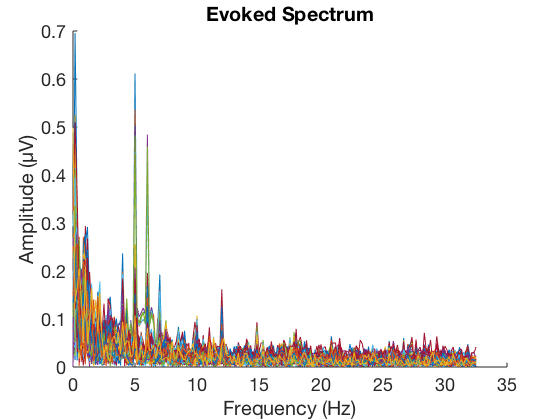

figure(3), plot(freqs(1:196), amp(:, 1:196))   
                                            
ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Amplitude (μV)') %label the axis
title([ 'Evoked Spectrum' ])

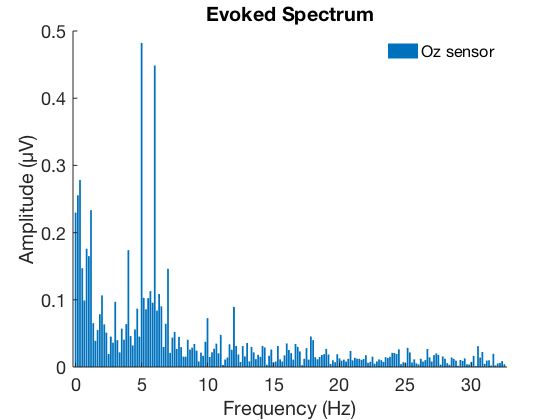


figure(4), bar(freqs(1:196), amp(75, 1:196)) %select Oz sensor (sensor #75)

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off' ;  %remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Amplitude (μV)') %label the axis
title([ 'Evoked Spectrum' ])
legend ('Oz sensor'), legend boxoff %add legend

## 7-Run FFT on single-trials

    -Instead of running the fft across the trials, in this analysis each trial will be transformed into the spectra domain. After computing the fft for all trials, the spectra of the single trials are averaged across the trials;

    -The function freqtag_FFT3D has two input arguments: the dataset (data_ssvep) and the sample rate (fsamp);

    - "amp" is  the average single trial spectrum represented as 2-D matrix: sensors-by-amplitude.

    - freqs are the frequencies available in the spectrum

    - fftcomp contains the complex spectra for the single trials, to be used for calculating error metrics, as well as indices reflective of systematic tendencies in the spectrum such as the circular Tsquare statistic, which is also supplied with this toolbox (freqtag_Tsquare.m)

[amp, freqs, fftcomp] = freqtag_FFT3D(data_ssvep, 500); %No need to average over the third dimension here.

## 8-Plot the FFT on single trials results

    -Plot the amplitude for each frequency, select the frequencies between 0 and 32.33 Hz (1:196);

    -On the y-axis, we plot is the output argument of the freqtag_FFT3D function, the "amp" variable containing the amplitude for ech frequency.

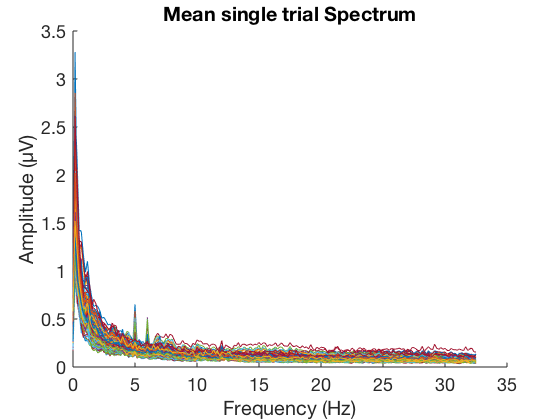

figure(5), plot(freqs(1:196), amp(:, 1:196))   %plot the all sensors 

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Amplitude (μV)') %label the axis
title([ 'Mean single trial Spectrum' ])

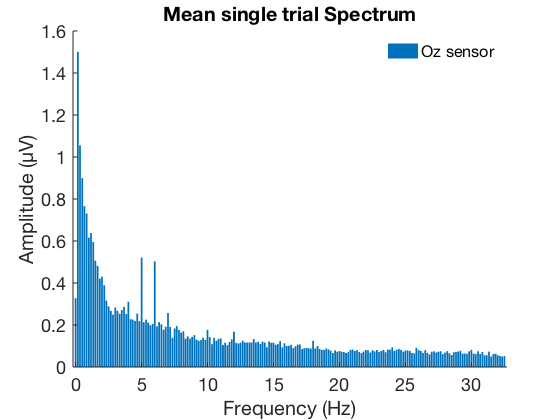


figure(6), bar(freqs(1:196), amp(75, 1:196))  %select Oz sensor (sensor #75)

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Amplitude (μV)') %label the axis
title([ 'Mean single trial Spectrum' ])
legend ('Oz sensor'), legend boxoff   %add legend

## 9-Run Hilbert Transform. First, selecting the 5Hz tagging frequency. Second, selecting the 6Hz frequency

    -The freqtag_hilb function takes as input arguments a 2-D data (sensors-by-time points) matrix, the stimulus frequency in Hz (taggingfreq), the order of the Butterworth filter (filterorder), the sensor to be plotted (sensor2plot)  with the phase-shifted (hilbert transformed) time series and the absolute value of the data and the analytical hilbert transformed time series, which represents the envelope of the ssVEP;  the option to plot or not to plot such information (plotfag) and the sampling rate (fsamp);

    -The input dataset is the time-domain average across trials, averaged in the third dimension (trial dimension). 

    -The function will plot the sensor Oz (sensor #75), but that can be modified according to the dataset to be analyzed. Although it is advisable to always visualize the data, the reader might turn this plot off by selecting zero or [] in the "plotfag" input argument;

    -In this plot the blue line is the filtered data, the red line is the imaginary part and the black line is the real part;

    -The function should be run for each presentation rate (taggingfreq). As always: if the output arguments have the same name, they will be overwritten. 

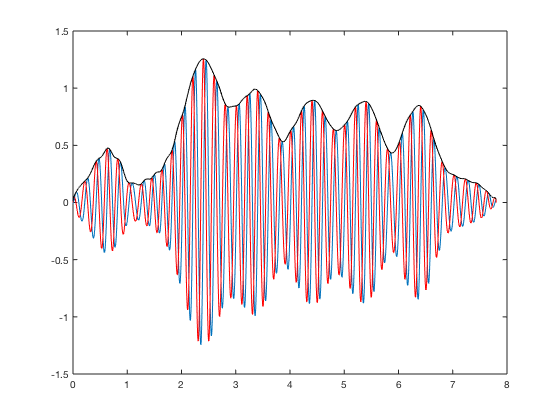

[amp5, phase5, complex5] = freqtag_HILB(mean(exampledata_1,3), 5, 10, 75, 1, 500);

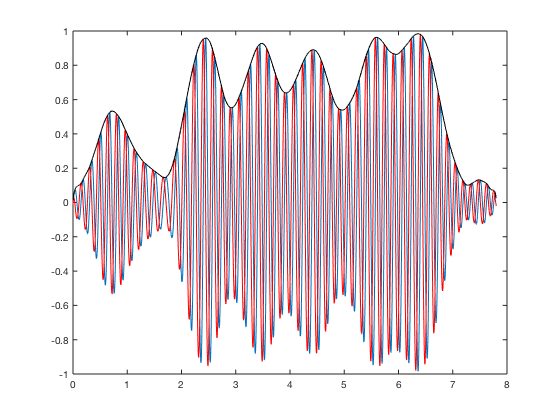

[amp6, phase6, complex6] = freqtag_HILB(mean(exampledata_1,3), 6, 10, 75, 1, 500);

## 10-Plot the Hilbert Transform results

Again, the vertical gray lines denote the onset and offset of the tagging array, respectively

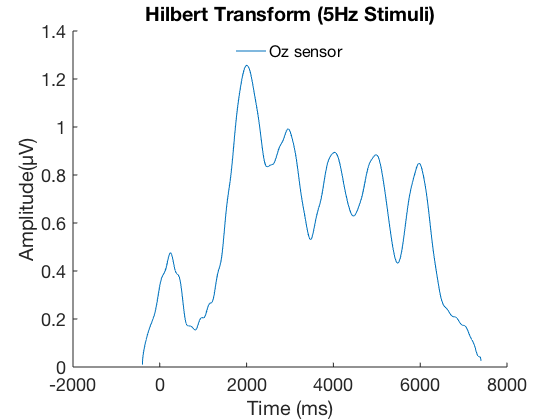

figure(7), p3 = plot(taxis, amp5(75, :)');   %select Oz sensor (sensor #75)

ax = gca;          %editing the plot
ax.FontSize = 18;  %set the font size
ax.Box = 'off';    %remove the box around the plot
xlabel('Time (ms)'), ylabel('Amplitude(μV)') %label the axis
title([ 'Hilbert Transform (5Hz Stimuli)' ])
% xline(1000); xline(7000);
legend (p3, 'Oz sensor', 'location', 'north'), legend boxoff  %add legend

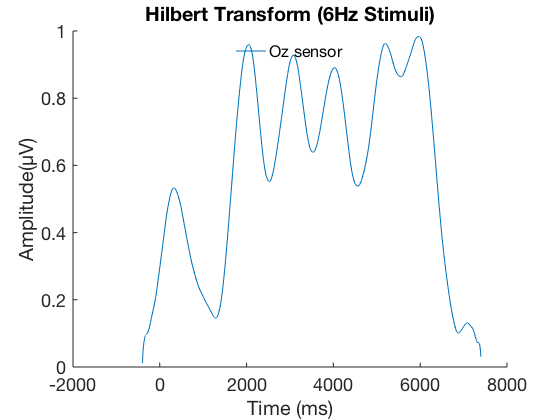


figure(8), p4 = plot(taxis, amp6(75, :)');  %select Oz sensor

ax = gca;          %editing the plot
ax.FontSize = 18;  %set the font size
ax.Box = 'off';    %remove the box around the plot
xlabel('Time (ms)'), ylabel('Amplitude(μV)') %label the axis
title([ 'Hilbert Transform (6Hz Stimuli)' ])
% xline(1000); xline(7000);
legend (p4, 'Oz sensor', 'location', 'north'), legend boxoff  %add legend

## 11-Close all figures

close all
